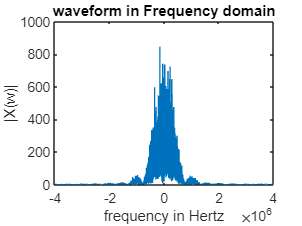

clc;
clear;

sps = 8;
[waveForm,fs] = generateBLEWaveform(sps);

% in frequency domain
plot(linspace(-fs/2, (fs/2)-(fs/length(waveForm)), length(waveForm)), abs(fftshift(fft(waveForm.'))))
title('waveform in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

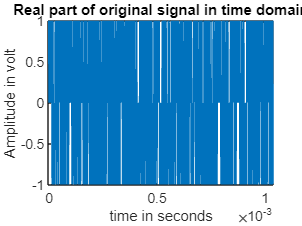

I = real(waveForm);
Q = imag(waveForm);
%%Real and imaginary part of Bluetooth signal
%In time domain
plot(1/fs*[0:length(waveForm)-1], I.')
title('Real part of original signal in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');

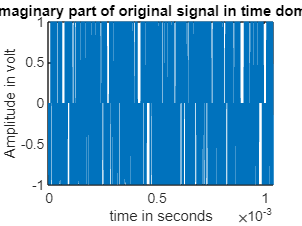

plot(1/fs*[0:length(waveForm)-1], Q.')
title('Imaginary part of original signal in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');

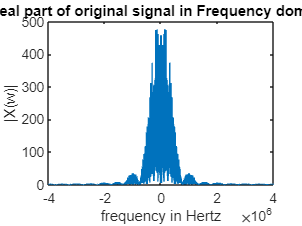


% in frequency domain
plot(linspace(-fs/2, (fs/2)-(fs/length(waveForm)), length(waveForm)), abs(fftshift(fft(I.'))))
title('real part of original signal in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

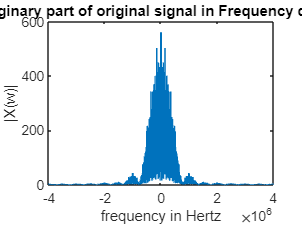


plot(linspace(-fs/2, (fs/2)-(fs/length(waveForm)), length(waveForm)), abs(fftshift(fft(Q.'))))
title('imaginary part of original signal in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');


%t = 0:1/fs:((length(waveForm)/fs)-(1/fs));
fc = 2428*10e6;
Bw = 0.9*10e6;
fs_new = (4*fc+2*Bw);
%t = 0:1/fs_new:((length(waveForm)/fs_new)-(1/fs_new));
%f = linspace(-fs_new/2, (fs/2)-(fs/length(waveForm)), length(t));
n = floor(fs_new/fs);

#### **Transmiting**

%upsampling
upSampled_real = upsample(I,n);
upSampled_imag = upsample(Q,n);

upSampled_wave = upsample(waveForm,n);

%interpolation
Hd = interpolation_filter;
upSampled_real = filter(Hd, upSampled_real);
upSampled_imag = filter(Hd, upSampled_imag);

upSampled_wave = filter(Hd, upSampled_wave);

%t = 1/fs_new*[0:length(upSampled_imag)-1];
%t_new = 1/fs_new*[0:length(upSampled_imag)-1];
%f = linspace(-fs_new/2, (fs_new/2)-(fs_new/length(waveForm)), length(t));


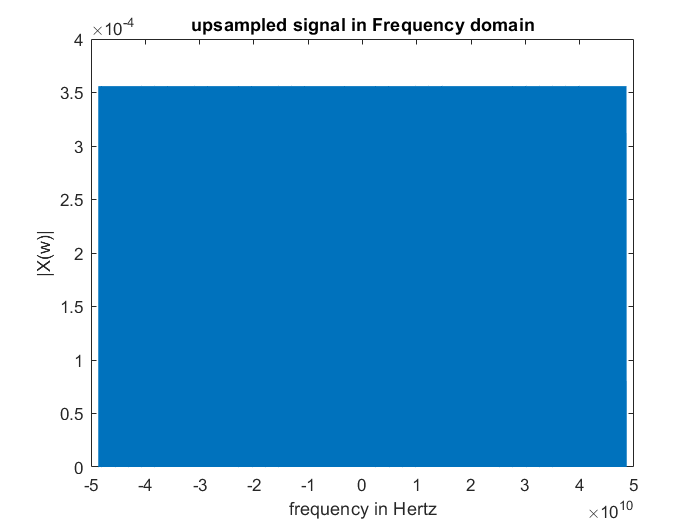


plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_wave)), length(upSampled_wave)), abs(fftshift(upSampled_wave.')))
uicontrol('Visible','off')
title('upsampled signal in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

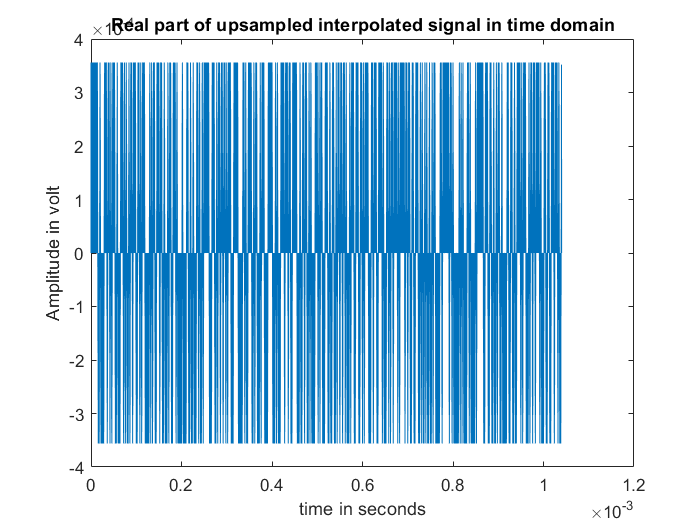

%%after upsampling
%%in time domain
plot( 1/fs_new*[0:length(upSampled_imag)-1], upSampled_real.');
uicontrol('Visible','off')
title('Real part of upsampled interpolated signal in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');

plot( 1/fs_new*[0:length(upSampled_imag)-1], upSampled_imag.');
uicontrol('Visible','off')
title('Imaginary part of upsampled interpolated signal in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');

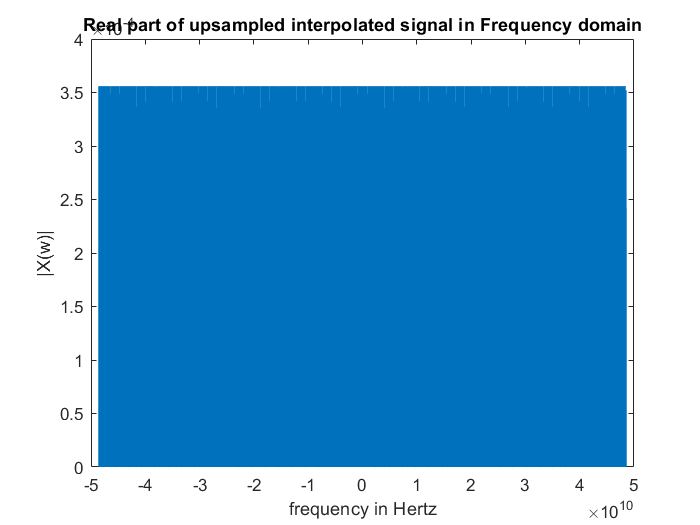

% in frequency domain
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(upSampled_real)), abs(fftshift(upSampled_real.')))
uicontrol('Visible','off')
title('Real part of upsampled interpolated signal in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

%plot(f,waveForm);
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(upSampled_real)), abs(fftshift(upSampled_imag.')))
uicontrol('Visible','off')
title('imaginary part of upsampled interpolated signal in Frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');
%plot(f,waveForm);

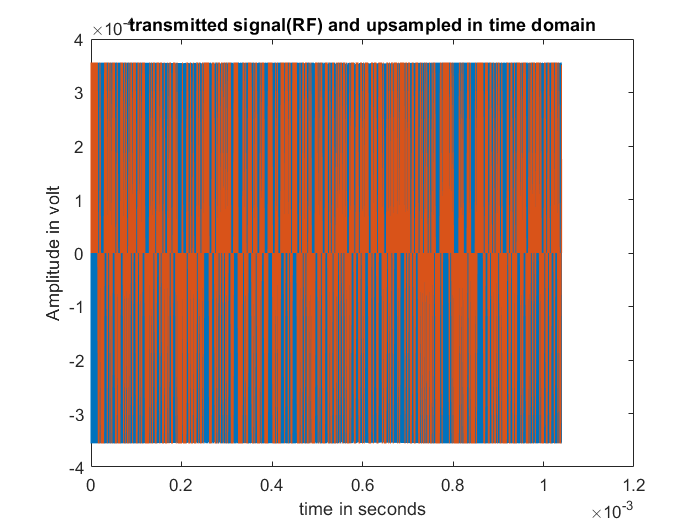

%carrier
transmited_signal = upSampled_real.*transpose(cos(2*pi*fc* (1/fs_new*[0:length(upSampled_imag)-1]))) + upSampled_imag.*transpose(sin(2*pi*fc*(1/fs_new*[0:length(upSampled_imag)-1])));
%%transmitted signal
plot((1/fs_new*[0:length(transmited_signal)-1]), transmited_signal.')
uicontrol('Visible','off')
hold on
title('transmitted signal(RF) and upsampled in time domain');
uicontrol('Visible','off')
xlabel('time in seconds');
ylabel('Amplitude in volt');
plot( 1/fs_new*[0:length(upSampled_imag)-1], upSampled_real.')
hold off

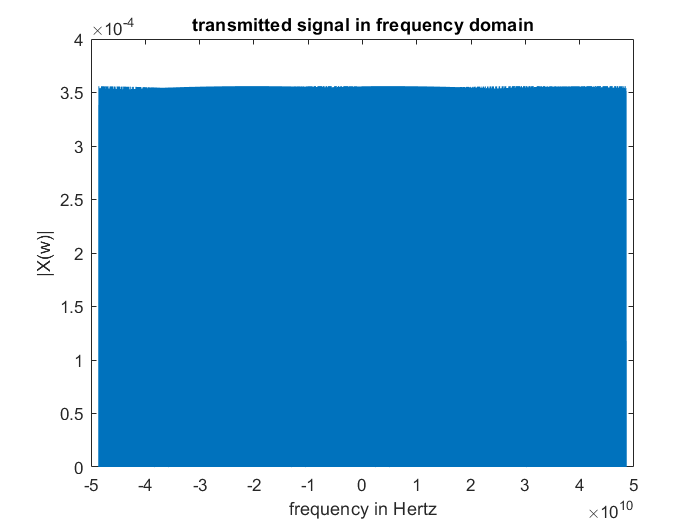

%in frequency domain
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_imag)), length((1/fs_new*[0:length(transmited_signal)-1]))), abs(fftshift(transmited_signal.')))
uicontrol('Visible','off')
title('transmitted signal in frequency domain');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

#### **Channel**

%channel
noisy_signal = awgn(transmited_signal, 10);


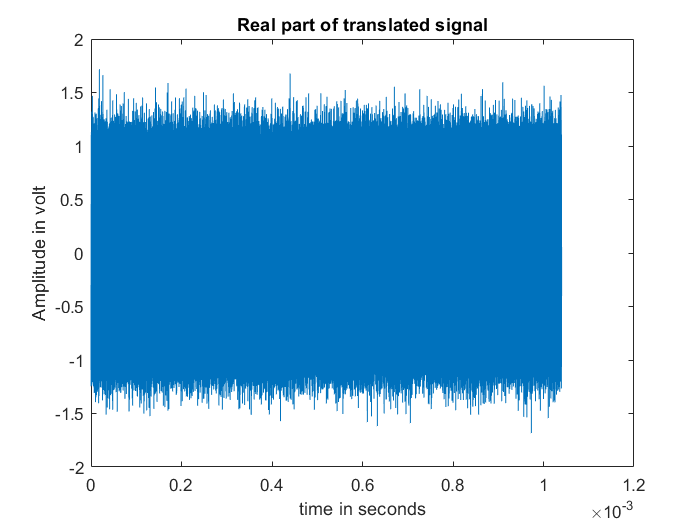

translated_real = noisy_signal .* transpose(cos(2*pi*fc*1/fs_new*[0:length(transmited_signal)-1]));
translated_imag = noisy_signal .* transpose(sin(2*pi*fc*1/fs_new*[0:length(transmited_signal)-1]));

plot(1/fs_new*[0:length(upSampled_imag)-1], translated_real.')
uicontrol('Visible','off')
title('Real part of translated signal');
xlabel('time in seconds');
ylabel('Amplitude in volt');

plot(1/fs_new*[0:length(upSampled_imag)-1], translated_imag.')
uicontrol('Visible','off')
title('Imaginary part of translated signal');
xlabel('time in seconds');
ylabel('Amplitude in volt');

% % in frequency domain
% plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(translated_real)), length((1/fs_new*[0:length(translated_real)-1]))), abs(fftshift(translated_real.')))
% uicontrol('Visible','off')
% title('Frequency domain  of translated real part');
% xlabel('frequency in Hertz');
% ylabel('|X(w)|');
% %plot(f,waveForm);

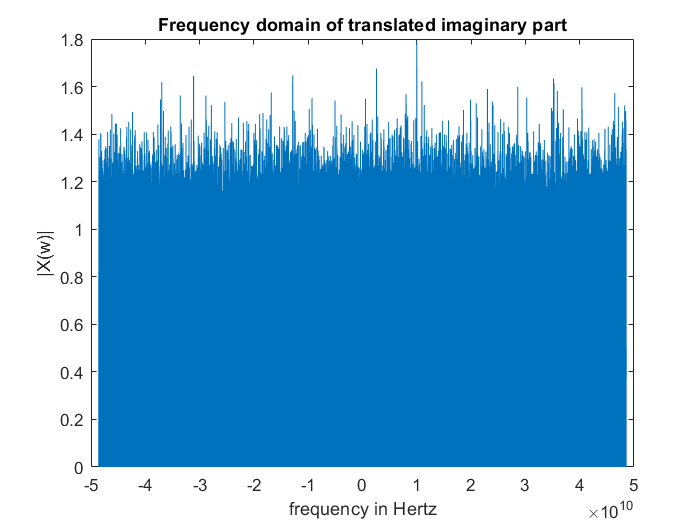

plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_imag)), length((1/fs_new*[0:length(transmited_signal)-1]))), abs(fftshift(translated_imag.')))
uicontrol('Visible','off')
title('Frequency domain of translated imaginary part');
xlabel('frequency in Hertz');
ylabel('|X(w)|');

%plot(f,waveForm);

filtered_real = filter(Hd, translated_real);
filtered_imag = filter(Hd, translated_imag);
%%filtered  signal
plot(1/fs_new*[0:length(filtered_real)-1], filtered_real.')
title('Real part of filtered signal in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');

% in frequency domain

plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(filtered_real)), abs(fftshift(filtered_real.')))
title('Frequency domain  of filtered real part');
xlabel('frequency in Hertz');
ylabel('|X(w)|');


%plot(f,waveForm);
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(filtered_imag)), abs(fftshift(filtered_imag.')))
uicontrol('Visible','off')
title('Frequency domain of filtered imaginary part');
xlabel('frequency in Hertz');
ylabel('|X(w)|');
%plot(f,waveForm);


%down sampling
output_real = downsample(filtered_real,n);
output_imag = downsample(filtered_imag,n);

%%outputs:
plot(1/fs*[0:length(waveForm)-1], Q.')
uicontrol('Visible','off')
hold on
title('Real part of output signal and original  in time domain');
uicontrol('Visible','off')
xlabel('time in seconds');
ylabel('Amplitude in volt');
plot(1/fs_new*[0:length(output_real)-1], output_real.')
hold off

plot(1/fs*[0:length(waveForm)-1], I.')
uicontrol('Visible','off')
hold on
title('Imaginary part of output signal and original  in time domain');
xlabel('time in seconds');
ylabel('Amplitude in volt');
plot(1/fs_new*[0:length(output_imag)-1], output_imag.')
uicontrol('Visible','off')
hold off

% in frequency domain
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(output_real)), abs(fftshift(output_real.')))
uicontrol('Visible','off')
title('Frequency domain  of output real part');
xlabel('frequency in Hertz');
ylabel('|X(w)|');
%plot(f,waveForm);
plot(linspace(-fs_new/2, (fs_new/2)-(fs_new/length(upSampled_real)), length(output_imag)), abs(fftshift(output_imag.')))
uicontrol('Visible','off')
title('Frequency domain of output imaginary part');
xlabel('frequency in Hertz');
ylabel('|X(w)|');
%plot(f,waveForm);


function [waveform,Fs] = generateBLEWaveform(sps)
%% Generating Bluetooth Low Energy waveform
% Bluetooth Low Energy configuration
% sps = 1;
symbolRate = 1000000;
% input bit source:
in = randi([0, 1], 1000, 1);


% Generation
waveform = bleWaveformGenerator(in, 'Mode', 'LE1M', ...
    'SamplesPerSymbol', sps, ...
    'ChannelIndex', 37, ...
    'AccessAddress', [0 1 1 0 1 0 1 1 0 1 1 1 1 1 0 1 1 0 0 1 0 0 0 1 0 1 1 1 0 0 0 1]');

Fs = sps * symbolRate; 

end


function Hd = interpolation_filter
%DECIMATION_FILTER Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.13 and DSP System Toolbox 9.15.
% Generated on: 02-Jan-2023 22:43:41

% FIR least-squares Lowpass filter designed using the FIRLS function.

% All frequency values are normalized to 1.

N     = 200;               % Order
Fpass = 0.00035153019024;  % Passband Frequency
Fstop = 0.00041356492969;  % Stopband Frequency
Wpass = 1;                 % Passband Weight
Wstop = 1;                 % Stopband Weight

% Calculate the coefficients using the FIRLS function.
b  = firls(N, [0 Fpass Fstop 1], [1 1 0 0], [Wpass Wstop]);
Hd = dfilt.dffir(b);

% [EOF]
end